%======================================================================
% ECSE 443 - Assignment 2
% Author ----- Tristan Bouchard
% Student ID - 260747124
% Submitted -- Sunday, February 24, 2019 at 1pm.
%======================================================================
addpath('./Functions/');


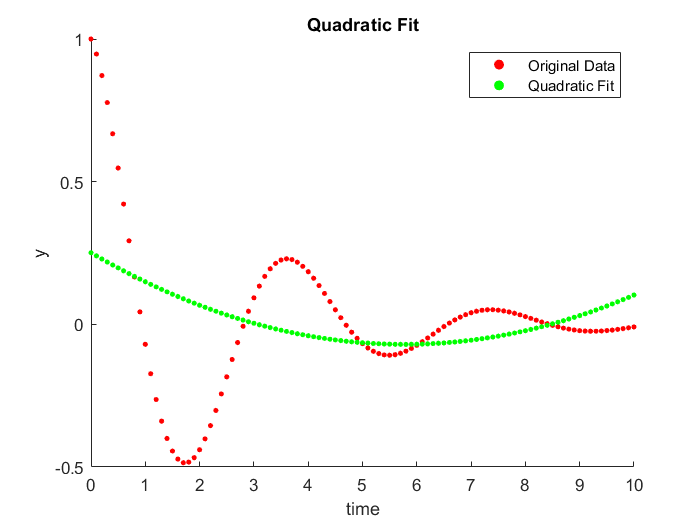

%======================================================================
% Question 1 (8 Marks) - Best Fit curve
%======================================================================

close all
clear

% Begin by importing the data given
dataQ1 = importData("Ass_2_Q1_data.txt");
time = dataQ1(:,1);
% Get Coefficients for a quadratic fit, using normal equations
coefficients = fitQuadratic(dataQ1);

% Compute scatter points from coefficients
quadraticScatter = computeQuadraticScatter(time,coefficients);
titlesQuad= ["Original Data", "Quadratic Fit"];
plotData(dataQ1, quadraticScatter, "No Data", titlesQuad, "Quadratic Fit", [-0.5, 1]);         

disp("Quadratic coefficients");

Quadratic coefficients


vpa(coefficients)

$$ans = \left(\begin{array}{c} 0.25092226257524147259303504142736\\ -0.11134591944917321404417975827528\\ 0.0096516433454205876468767755227418 \end{array}\right)$$

% Compute Square error
error = squareError(dataQ1, quadraticScatter);
disp("Square error for quadratic fit = "+error);

Square error for quadratic fit = 6.3286


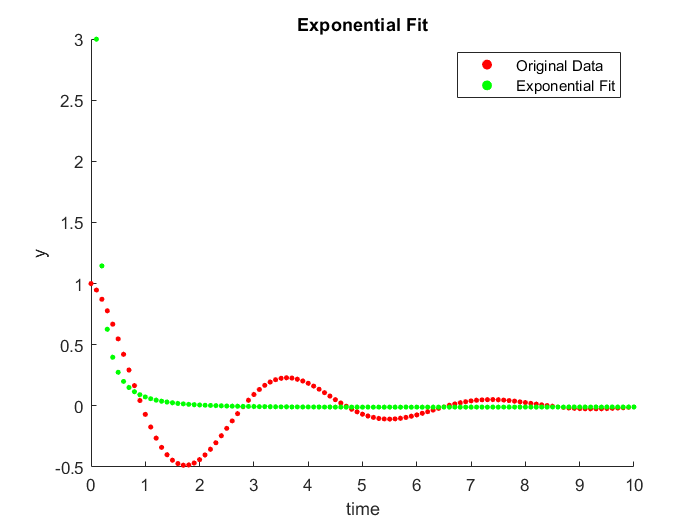


% Get coefficients for function 2 in the chart
% Use a logarithmic solution, such that we can still use the method
% of normalized equations. We thus solve for log(y) = log(a0) + a1*log(t)
coefficientsExponential = fitExponential(dataQ1);

% Compute Scatter for exponential fit to graph
% Here, we omit the time = 0 point, as we need to compute the logarithm of
% the data, which cannot be done with a 0 data point
exponentialScatter = computeExponentialScatter(dataQ1(2:end, 1), coefficientsExponential);

% Plot exponential curve fit versus the original data
titlesExp = ["Original Data", "Exponential Fit"];
plotData(dataQ1, real(exponentialScatter), "No Data",titlesExp, "Exponential Fit", [-0.5, 3]);

disp("Exponential coefficients");

Exponential coefficients


vpa(coefficientsExponential)

$$ans = \left(\begin{array}{cc} 0.072688765244001349308256010317564+0.29459218675410148158277934271609\,\mathrm{i} & -1.1094342674180712737808107704041+0.27537675127287075671489446904161\,\mathrm{i} \end{array}\right)$$

% Compute Square error
error = squareError(dataQ1(2:length(time),:), real(exponentialScatter));
disp("Square error for exponential fit = "+error);

Square error for exponential fit = 7.5619


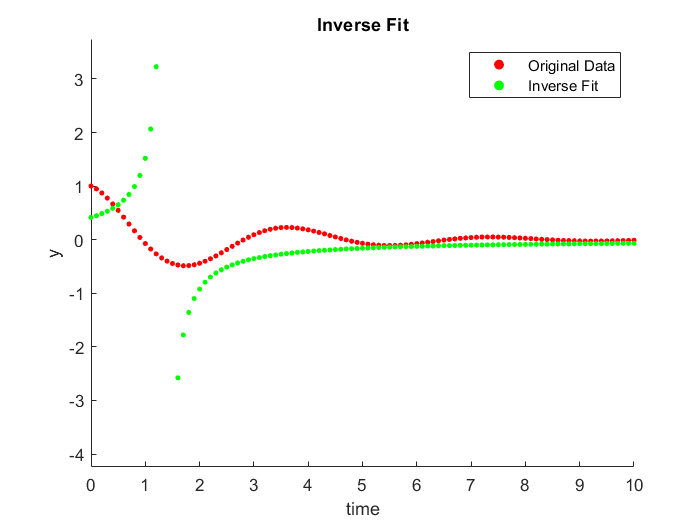


% Compute fitment for inverse-type function.
coefficientsInverse = fitInverse(dataQ1);

% Compute scatter points and plot the fit curve over the original data
inverseScatter = computeInverseScatter(time, coefficientsInverse);
titlesExp = ["Original Data", "Inverse Fit"];
plotData(dataQ1, inverseScatter, "No Data", titlesExp, "Inverse Fit", [-3, 3]);

disp("Inverse coefficients");

Inverse coefficients


vpa(coefficientsInverse)

$$ans = \left(\begin{array}{c} 2.4035905068901932679636956891045\\ -1.7448462148399295212897186502232 \end{array}\right)$$

% Compute Square error
error = squareError(dataQ1, inverseScatter);
disp("Square error for inverse fit = "+error);

Square error for inverse fit = 743.4615


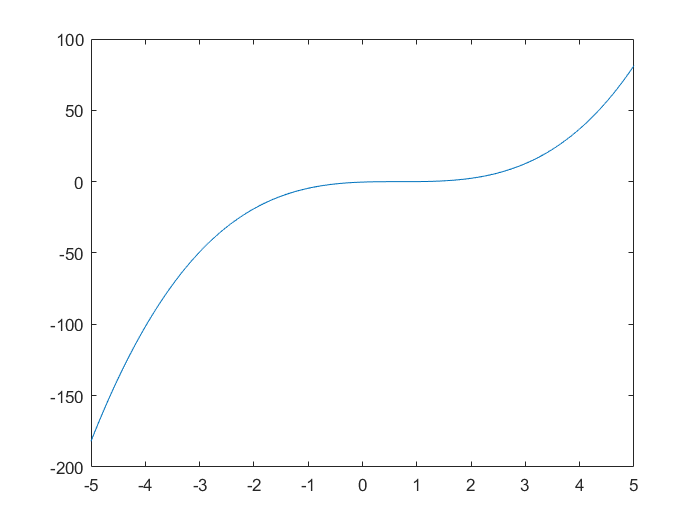

%======================================================================
% Question 2 (6 Marks) - Root Finding
% Using the bi-section method to find the roots of the function
%======================================================================

% This section will be completed using the algorithm described in the class
% notes for the bi-section method
close all
clear
% Use the long format to obtain required precision
format long

syms x;
f(x) = x^3 - 2*x^2 + (4/3)*x - (8/27);
% Define precision to compute roots
tol = (1*10^(-8));

t = [-5:0.01: 5];
eff = t.^3 - 2*t.^2 + (4/3)*t - (8/27);
plot(t,eff);

% Pick initial bracket where we suspect to have roots.
a = -10;
b = 10;
% We expect three roots from the third order Polynomial
numRoots = 3;

bisectionRoots = bisection(f,a,b,tol,numRoots);

% Compare with roots computed by the base matlab functions
trueRoots = double(solve(f));

disp("The roots computed by the bisection method = ");

The roots computed by the bisection method = 


disp(bisectionRoots);

   0.666666673496366
   0.666666673496366
   0.666666673496366



disp("The roots computed by MATLAB = ");

The roots computed by MATLAB = 


disp(trueRoots);

   0.666666666666667
   0.666666666666667
   0.666666666666667



error = bisectionRoots - trueRoots;
disp("The error between the roots = ");

The error between the roots = 


disp(error);

   1.0e-08 *

   0.682969891752094
   0.682969891752094
   0.682969891752094



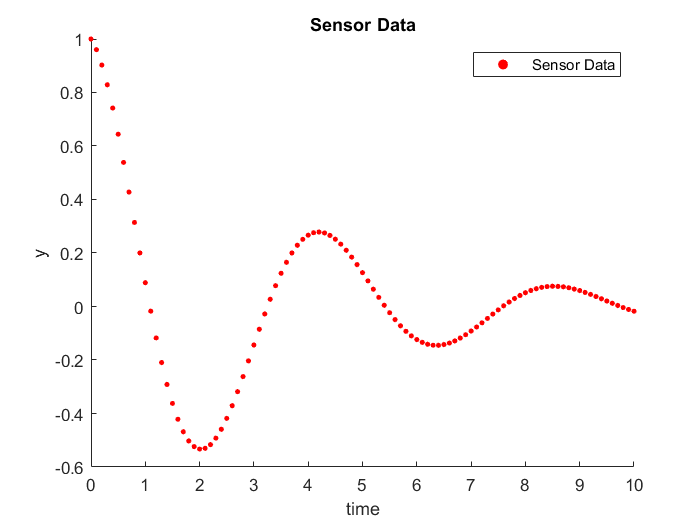

%======================================================================
% Question 3 (8 Marks) - Frequency using the Secant Method
% Find the frequency of a signal using the secant method and my knowledge
% of the signal
%======================================================================

close all
clear
format long

% Import data from file and plot
dataQ3 = importData("Ass_2_Q3_data");
time = dataQ3(:,1);
data = dataQ3(:,2);
plotData(dataQ3,"No Data", "No Data","Sensor Data","Sensor Data");

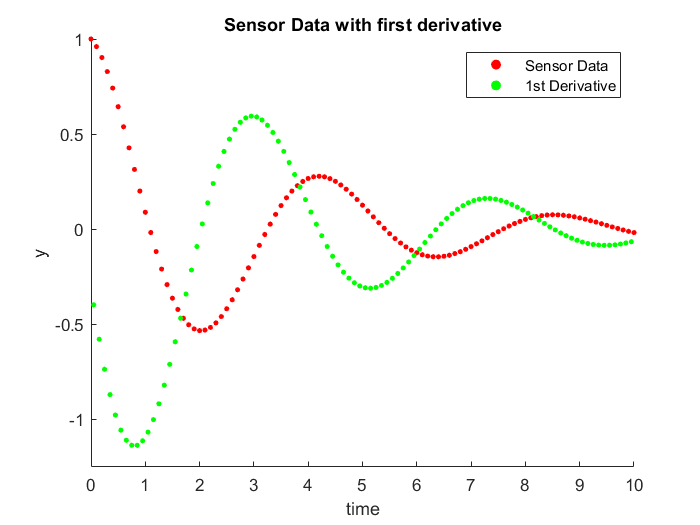


% We know that a signal that is periodic has a period equal to 1/frequency. Such,
% if we assume that the data is periodic, which it does resemble even with some
% attenuation, all I have to do to find the frequency of the signal is find 
% the distance between those two points at which the function repeats.

% To achieve this, I will find the distance between the two negative peaks,
% as we conveniently have two negative peaks in the data. To do this, I
% will find the roots of the first derivative of the function, where the
% roots signal the transition between the downard slope and upward slope.
% These roots should occur in the time range [1, 3] and [5, 7]

% Compute the first derivative
h = time(2);
der = diff(data);
% Compute the new time where the derivative was computed, i.e. between
% intervals of the data time
derivativeTime = (time(1:length(time)-1, :) + time(2:end))/2;
derivative = [derivativeTime der/h];
legendTitles = ["Sensor Data", "1st Derivative"];
title = "Sensor Data with first derivative";
yScale = [-1.25 1];
plotData(dataQ3,derivative, "No Data",legendTitles,title,yScale);


%Find the roots using the secant method
% Want good precision
tol = 1*10^(-8);
% Pick values close to expexted roots but also
% such that algorithm does not crash :/
x0 = 1.25;
x1 = 1.55;
zero1 = secantRootFinding(derivative, x0, x1, tol, 100);
% Pick values such that algorithm does not crash :/
x2 = 5.55;
x3 = 5.85;
zero2 = secantRootFinding(derivative, x2, x3, tol, 100);

frequency = double(1/(zero2 -zero1));
disp("Calculated frequency = "+frequency)

Calculated frequency = 0.2308


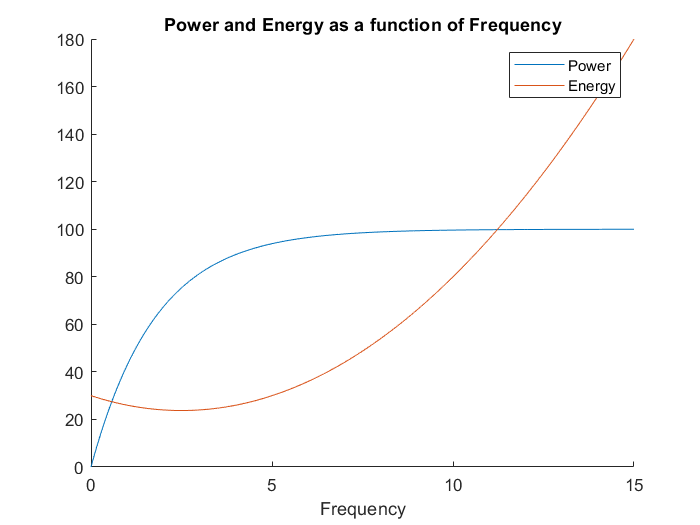

%======================================================================
% Question 4 (8 Marks) - Crossings using Newton Method
%======================================================================

close all
clear
format longeng
% Given the following functions of the generator, make symbolic
syms w;
P(w) = 100*(1-exp(-0.56*w));
E(w) = w^2 - 5*w + 30;

% Plot functions to get an idea what they look like:
t = [0:0.01:15];
Pow = 100*(1-exp(-0.56*t));
Ener = t.^2 - 5.*t + 30;

hold on
plot(t,Pow);
plot(t,Ener);
legend("Power", "Energy");
title("Power and Energy as a function of Frequency")
xlabel("Frequency");
ylabel("")
hold off


% In order to find solutions to this equation, must subtract them from one
% another, then find the roots of the equation! Because we have the actual
% functions and not just data, we can actually use newtons method instead
% of the secant method.

sub = P - E;

% Compute the first root of the equation.
tol = 1*10^(-8);
maxIterations = 50;
xStart = 0;
root1 = double(newtonRootFinding(sub, xStart, tol, maxIterations));

% Compute the second root of the equation, around w = 12.
% Pick start around 10
xStart = 10;
root2 = double(newtonRootFinding(sub, xStart, tol, maxIterations));

disp("The operating frequencies are:");

The operating frequencies are:


vpa(root1)

$$ans = 0.57332284528293742109639197224169$$

disp("and");

and


vpa(root2)

$$ans = 11.222086510495158151456962514203$$

disp("kHz");

kHz
